clc
clear all

## **Initializig the space and Witt Basis**

clifford_signature(8,0)
%// Imaginary unit
%i = er1*er2;
%// Witt basis
f1 = 0.5*(e1 + i*e5); 
f1T = 0.5*(e1 - i*e5); 
f2 = 0.5*(e2 + i*e6); 
f2T = 0.5*(e2 - i*e6);
f3 = 0.5*(e3 + i*e7); 
f3T = 0.5*(e3 - i*e7); 
f4 = 0.5*(e4 + i*e8); 
f4T = 0.5*(e4 - i*e8);

## Defining the states of the 4 qubit system

%// Element "I"
Id = f1*f1T*f2*f2T*f3*f3T*f4*f4T;
%// ket basis vectors multiplied by "Id" 11 
ket0000 = 1*Id;
ket0001 = f4T*Id

ket0001 =    0.0625 e4       + ( 0.0000 - 0.0625i) e8      
   ( 0.0000 + 0.0625i) e145     - 0.0625 e158     + ( 0.0000 + 0.0625i) e246     - 0.0625 e268     + ( 0.0000 + 0.0625i) e347     - 0.0625 e378    
 + 0.0625 e12456   + ( 0.0000 - 0.0625i) e12568   + 0.0625 e13457   + ( 0.0000 - 0.0625i) e13578   + 0.0625 e23467   + ( 0.0000 - 0.0625i) e23678  
   ( 0.0000 + 0.0625i) e1234567 - 0.0625 e1235678

ket0010 = f3T*Id;
ket0100 = f2T*Id;
ket0011 = f3T*f4T*Id;
ket0101 = f2T*f4T*Id;
ket0110 = f2T*f3T*Id;
ket0111 = f2T*f3T*f4T*Id;
ket1000 = f1T*Id;
ket1001 = f1T*f4T*Id

ket1001 =    0.0625 e14      + ( 0.0000 - 0.0625i) e18      + ( 0.0000 + 0.0625i) e45      - 0.0625 e58     
   ( 0.0000 + 0.0625i) e1246    - 0.0625 e1268    + ( 0.0000 + 0.0625i) e1347    - 0.0625 e1378    + 0.0625 e2456    + ( 0.0000 - 0.0625i) e2568    + 0.0625 e3457    + ( 0.0000 - 0.0625i) e3578   
 + 0.0625 e123467  + ( 0.0000 - 0.0625i) e123678  + ( 0.0000 + 0.0625i) e234567  - 0.0625 e235678 

ket1010 = f1T*f3T*Id;
ket1100 = f1T*f2T*Id;
ket1011 = f1T*f3T*f4T*Id;
ket1101 = f1T*f2T*f4T*Id;
ket1110 = f1T*f2T*f3T*Id;
ket1111 = f1T*f2T*f3T*f4T*Id;


## Gate implementations

%// Not operation
not1 = f1 +f1T;
not2 = f2 +f2T;
not3 = f3 +f3T;
not4 = f4 +f4T;
%//controlled z
cz12 = f1*f1T + f1T*f1*f2*f2T - f1T*f1*f2T*f2;
cz13 = f1*f1T + f1T*f1*f3*f3T - f1T*f1*f3T*f3;
cz24 = f2*f2T + f2T*f2*f4*f4T - f2T*f2*f4T*f4;
cz34 = f3*f3T + f3T*f3*f4*f4T - f3T*f3*f4T*f4;

%//hadamard
h1 = (1/sqrt(2))*(f1*f1T + f1  + f1T - f1T*f1);
h2 = (1/sqrt(2))*(f2*f2T + f2  + f2T - f2T*f2);
h3 = (1/sqrt(2))*(f3*f3T + f3  + f3T - f3T*f3);
h4 = (1/sqrt(2))*(f4*f4T + f4  + f4T - f4T*f4);

## Oracle function

%//superposition
psi = h1*h2*h3*h4*ket0000

psi =    0.0156 e0      
 + 0.0156 e1       + 0.0156 e2       + 0.0156 e3       + 0.0156 e4       + ( 0.0000 - 0.0156i) e5       + ( 0.0000 - 0.0156i) e6       + ( 0.0000 - 0.0156i) e7       + ( 0.0000 - 0.0156i) e8      
 + 0.0156 e12      + 0.0156 e13      + 0.0156 e14      + ( 0.0000 - 0.0156i) e15      + ( 0.0000 - 0.0156i) e16      + ( 0.0000 - 0.0156i) e17      + ( 0.0000 - 0.0156i) e18      + 0.0156 e23      + 0.0156 e24      + ( 0.0000 + 0.0156i) e25      + ( 0.0000 - 0.0156i) e26      + ( 0.0000 - 0.0156i) e27      + ( 0.0000 - 0.0156i) e28      + 0.0156 e34      + ( 0.0000 + 0.0156i) e35      + ( 0.0000 + 0.0156i) e36      + ( 0.0000 - 0.0156i) e37      + ( 0.0000 - 0.0156i) e38      + ( 0.0000 + 0.0156i) e45      + ( 0.0000 + 0.0156i) e46      + ( 0.0000 + 0.0156i) e47      + ( 0.0000 - 0.0156i) e48      - 0.0156 e56      - 0.0156 e57      - 0.0156 e58      - 0.0156 e67      - 0.0156 e68      - 0.0156 e78     
 + 0.0156 e123     + 0.0156 e124     + ( 0.0000 + 0.0156i) e125  


%//oracle
psi1 = psi;
%//12
psi1 = not1*cz12*not1*psi1;
%//13
psi1 = not3*cz13*not3*psi1;
%//24
psi1 = not2*cz24*not2*psi1;
%34
psi1 = not4*cz34*not4*psi1;
%multi controlled z
mcz = f1*f1T + f1T*f1*(f2*f2T + f2T*f2*(f3*f3T + f3T*f3*(f4*f4T - f4T*f4)));
psi1 = mcz*psi1;
psi1 = mcz*not4*not3*not2*not1*psi1;
psi1 = not1*not2*not3*not4*psi1;
psi1 = -1*psi1;


## Diffusion operator

%//diffusion
diffusion  = h1*h2*h3*h4*not1*not2*not3*not4*mcz*not4*not3*not2*not1*h4*h3*h2*h1;
%diffusion  = h4*h3*h2*h1*not4*not3*not2*not1*h4*Toff4*h4*not1*not2*not3*not4*h1*h2*h3*h4;
psi2 = diffusion*psi1;
%psi2 = psi2;

## Repeating the Grover application

psi1 = -psi2;
%//12
psi1 = not1*cz12*not1*psi1;
%//13
psi1 = not3*cz13*not3*psi1;
%//24
psi1 = not2*cz24*not2*psi1;
%34
psi1 = not4*cz34*not4*psi1;
%multi controlled z
mcz = f1*f1T + f1T*f1*(f2*f2T + f2T*f2*(f3*f3T + f3T*f3*(f4*f4T - f4T*f4)));
psi1 = mcz*psi1;
psi1 = mcz*not4*not3*not2*not1*psi1;
psi1 = not1*not2*not3*not4*psi1;
psi1 = -1*psi1

psi1 =    0.0078 e0      
 + 0.0078 e1       + 0.0078 e2       + 0.0078 e3       + 0.0078 e4       + ( 0.0000 - 0.0078i) e5       + ( 0.0000 - 0.0078i) e6       + ( 0.0000 - 0.0078i) e7       + ( 0.0000 - 0.0078i) e8      
 + 0.0078 e12      + 0.0078 e13      - 0.0391 e14      + ( 0.0000 - 0.0078i) e15      + ( 0.0000 - 0.0078i) e16      + ( 0.0000 - 0.0078i) e17      + ( 0.0000 + 0.0391i) e18      - 0.0391 e23      + 0.0078 e24      + ( 0.0000 + 0.0078i) e25      + ( 0.0000 - 0.0078i) e26      + ( 0.0000 + 0.0391i) e27      + ( 0.0000 - 0.0078i) e28      + 0.0078 e34      + ( 0.0000 + 0.0078i) e35      + ( 0.0000 - 0.0391i) e36      + ( 0.0000 - 0.0078i) e37      + ( 0.0000 - 0.0078i) e38      + ( 0.0000 - 0.0391i) e45      + ( 0.0000 + 0.0078i) e46      + ( 0.0000 + 0.0078i) e47      + ( 0.0000 - 0.0078i) e48      - 0.0078 e56      - 0.0078 e57      + 0.0391 e58      + 0.0391 e67      - 0.0078 e68      - 0.0078 e78     
 + 0.0078 e123     + 0.0078 e124     + ( 0.0000 + 0.0078i) e125 


%//diffusion
diffusion  = h1*h2*h3*h4*not1*not2*not3*not4*mcz*not4*not3*not2*not1*h4*h3*h2*h1;
%diffusion  = h4*h3*h2*h1*not4*not3*not2*not1*h4*Toff4*h4*not1*not2*not3*not4*h1*h2*h3*h4;
psi2 = diffusion*psi1

psi2 =    0.0039 e0      
 + 0.0039 e1       + 0.0039 e2       + 0.0039 e3       + 0.0039 e4       + ( 0.0000 - 0.0039i) e5       + ( 0.0000 - 0.0039i) e6       + ( 0.0000 - 0.0039i) e7       + ( 0.0000 - 0.0039i) e8      
 + 0.0039 e12      + 0.0039 e13      - 0.0430 e14      + ( 0.0000 - 0.0039i) e15      + ( 0.0000 - 0.0039i) e16      + ( 0.0000 - 0.0039i) e17      + ( 0.0000 + 0.0430i) e18      - 0.0430 e23      + 0.0039 e24      + ( 0.0000 + 0.0039i) e25      + ( 0.0000 - 0.0039i) e26      + ( 0.0000 + 0.0430i) e27      + ( 0.0000 - 0.0039i) e28      + 0.0039 e34      + ( 0.0000 + 0.0039i) e35      + ( 0.0000 - 0.0430i) e36      + ( 0.0000 - 0.0039i) e37      + ( 0.0000 - 0.0039i) e38      + ( 0.0000 - 0.0430i) e45      + ( 0.0000 + 0.0039i) e46      + ( 0.0000 + 0.0039i) e47      + ( 0.0000 - 0.0039i) e48      - 0.0039 e56      - 0.0039 e57      + 0.0430 e58      + 0.0430 e67      - 0.0039 e68      - 0.0039 e78     
 + 0.0039 e123     + 0.0039 e124     + ( 0.0000 + 0.0039i) e125 

## **Plotting of the results**

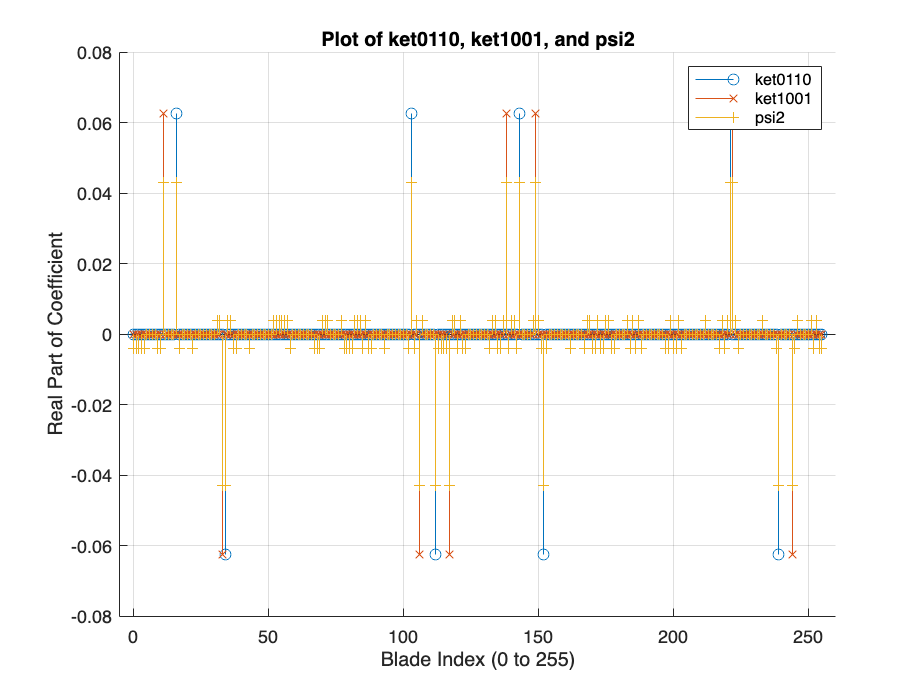

c1 = coefficients(ket0110);
c2 = coefficients(ket1001);
c3 = coefficients(-psi2);

% Convert to numeric arrays
c1_numeric = zeros(1, length(c1));
for k = 1:length(c1)
    if ~isempty(c1{k})
        c1_numeric(k) = c1{k};
    end
end

c2_numeric = zeros(1, length(c2));
for k = 1:length(c2)
    if ~isempty(c2{k})
        c2_numeric(k) = c2{k};
    end
end

c3_numeric = zeros(1, length(c3));
for k = 1:length(c3)
    if ~isempty(c3{k})
        c3_numeric(k) = c3{k};
    end
end
figure;
hold on;
stem(0:255, real(c1_numeric), 'o', 'DisplayName', 'ket0110');
stem(0:255, real(c2_numeric), 'x', 'DisplayName', 'ket1001');
stem(0:255, real(c3_numeric), '+', 'DisplayName', 'psi2');
hold off;
legend show;
xlabel('Blade Index (0 to 255)');
ylabel('Real Part of Coefficient');
title('Plot of ket0110, ket1001, and psi2');
grid on;